Directory "C:\Users\joaoa\Documents\[EU]Faculdade\Tese\SAR_Imaging_NNs_Thesis\Trials\06_03_2025-12_54_06\min_sample-100_max_range-2500_v-8_rdrhgt-1000" created successfully.


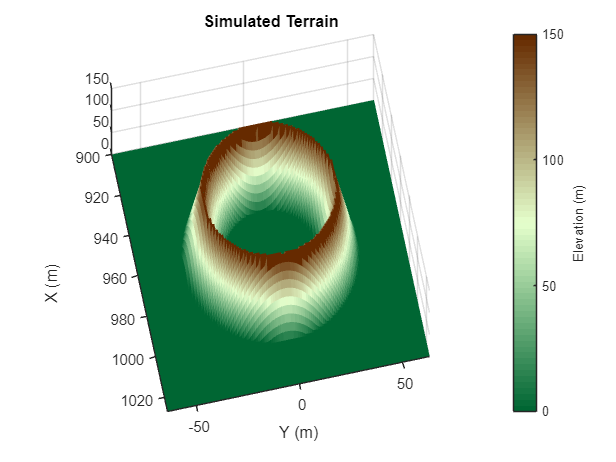

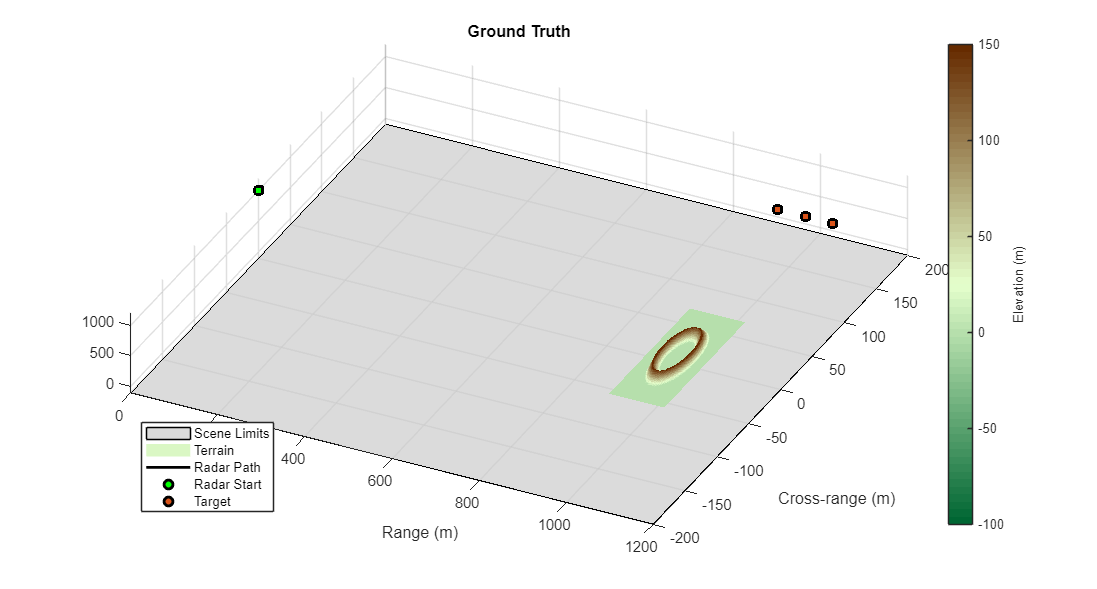

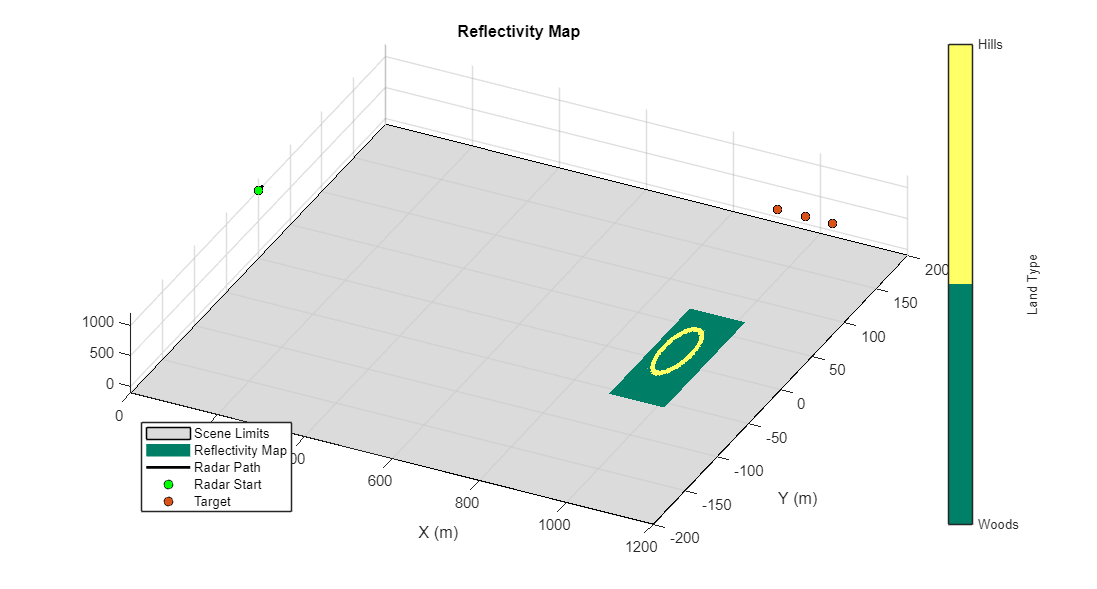

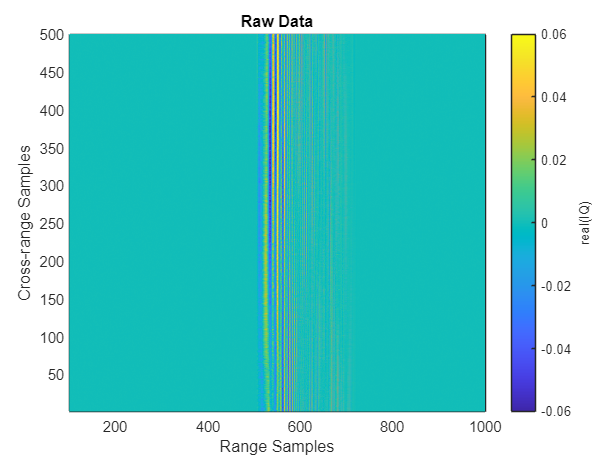

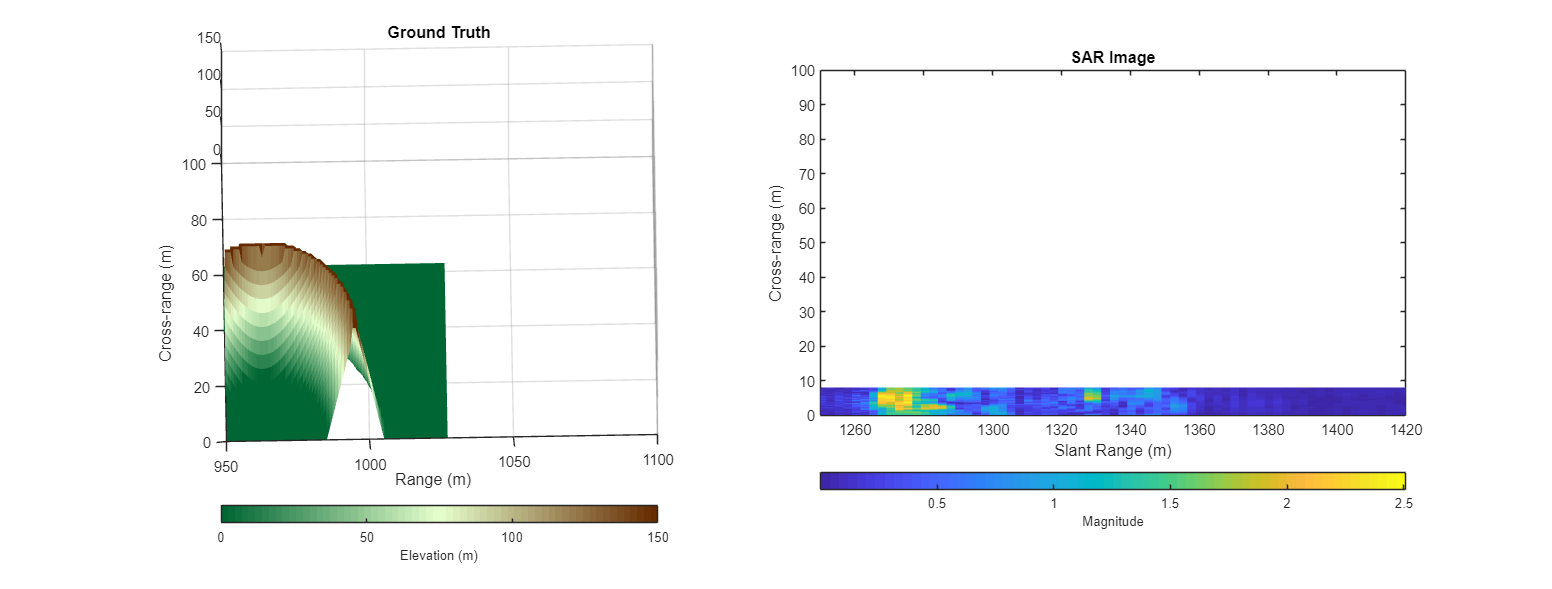

% Initialize random number generator
clear all;

t_start_global = datetime('now', 'Format', 'HH:mm:ss');

folder_dir = 'Trials\' + string(datetime('now', 'Format', 'dd_MM_yyy-HH_mm_ss'));

SARImageFormation_TerrainGenerator (folder_dir, true,  100, 2500, 8, 1000);

%SARImageFormation_TerrainGenerator (folder_dir, true,  330, 1153, 8, 500);

trial_number = 0;
duration_list = [];

%min_sample = 350;
v = 8;

for min_sample = 150:100:1050
    max_range = 1128 + ((min_sample-325)*2.5);

%rdrhgt = 490

% for v = 8:6.4:40
    
    for rdrhgt = 400:20:600
    
        t_start = datetime('now', 'Format', 'HH:mm:ss');
    
        %(dest_folder_name, have_plots, min_sample_input.
        %  , max_range_input, v_plat, rdr_hgt)
        SARImageFormation_TerrainGenerator (folder_dir, false,  min_sample, max_range, v, rdrhgt);
    
        trial_number = trial_number + 1;
    
        t_end = datetime('now', 'Format', 'HH:mm:ss');
    
        duration = t_end - t_start;
    
        duration_list = [duration_list; min_sample, max_range,v,rdrhgt, duration];
    
        disp(['Trial Nr.', num2str(trial_number), ' TOTAL RUNTIME: ', char(duration)]);
    end
% end
end



%útlima execução: min_sample-550_max_range-2500_v-40_rdrhgt-1000
%falhou na execução: min_sample-700_max_range-1500_v-8_rdrhgt-100

% for min_sample = 100:150:1000
% 
%     for max_range = 1500:200:2500
% 
%         for v = 8:6.4:40
% 
%             for rdrhgt = 100:180:1000
% 
%                 t_start = datetime('now', 'Format', 'HH:mm:ss');
% 
%                 %(dest_folder_name, have_plots, min_sample_input, max_range_input, v_plat, rdr_hgt)
%                 SARImageFormation_TerrainGenerator (folder_dir, false,  min_sample, max_range, v, rdrhgt);
% 
%                 trial_number = trial_number + 1;
% 
%                 t_end = datetime('now', 'Format', 'HH:mm:ss');
% 
%                 duration = t_end - t_start;
% 
%                 duration_list = [duration_list; min_sample, max_range,v,rdrhgt, duration];
% 
%                 disp(['Trial Nr.', num2str(trial_number), ' TOTAL RUNTIME: ', char(duration)]);
%             end
% 
%         end
% 
%     end
% end

t_end_global = datetime('now', 'Format', 'HH:mm:ss');

%SARImageFormation_TerrainGenerator ('Trials', 500, 2500);
